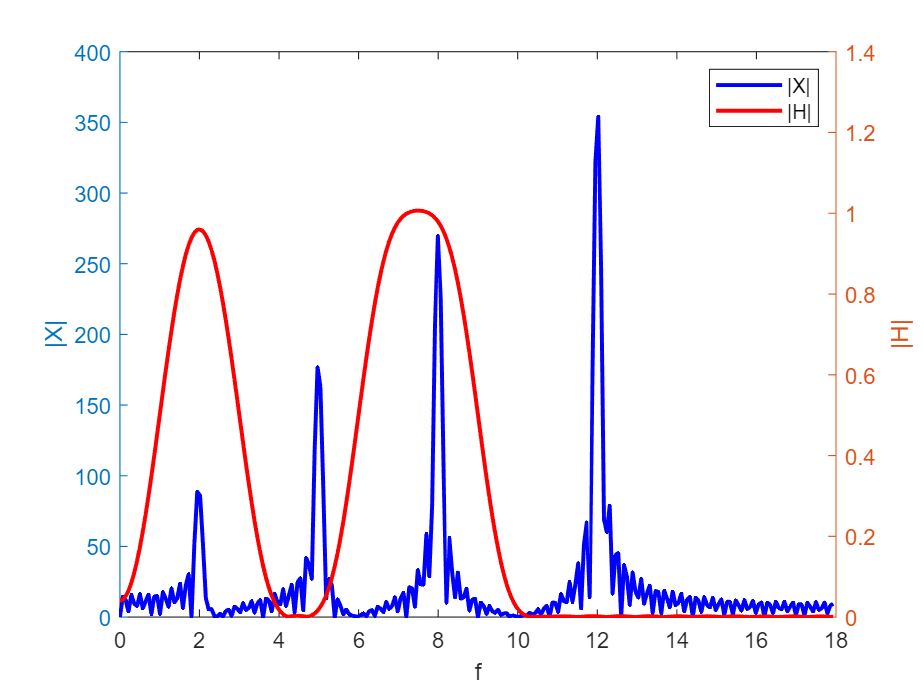

clc; clear; close all;
A1 = 1; f1 = 2;
A2 = 2; f2 = 5;
A3 = 3; f3 = 8;
A4 = 4; f4 = 12;
fs = 36; ts = 1/fs;
t = 0:ts:5;
x1 = A1*sin(2*pi*f1*t);
x2 = A2*sin(2*pi*f2*t);
x3 = A3*sin(2*pi*f3*t);
x4 = A4*sin(2*pi*f4*t);
xn = x1 + x2 + x3 + x4;
x13=x1+x3;
N = 50; 
fc1 = 1; % Tần số cắt thấp
fc2 = 3; % Tần số cắt cao

omega_c1 = 2*pi*fc1*ts;
omega_c2 = 2*pi*fc2*ts;
[hn_BP] = a0_ThongDai(omega_c1, omega_c2, N);
[w] = b0_Hamming(N);
hn1 = hn_BP.* w;
xL1 = conv(xn,hn1);

fc1 = 6; % Tần số cắt thấp
fc2 = 9; % Tần số cắt cao
omega_c1 = 2*pi*fc1*ts;
omega_c2 = 2*pi*fc2*ts;
[hn_BP] = a0_ThongDai(omega_c1, omega_c2, N);
[w] = b0_Hamming(N);
hn2 = hn_BP.* w;
xL2 = conv(xn,hn2);

xL = xL1+xL2;
% ============ Phổ của tín hiệu và của Lọc thông qua
Nfft = 500;
Xw = fft(xn,Nfft);
hn=hn1+hn2;
Hw = fft(hn,Nfft);
delta = fs/Nfft;
f = 0:delta:fs/2 - delta;
figure(1);
yyaxis left
plot(f,abs(Xw(1:Nfft/2)),'b-','linewidth',1.8); hold on;
xlabel('f'); ylabel('|X|');
yyaxis right
plot(f,abs(Hw(1:Nfft/2)),'r-','linewidth',1.8);
xlabel('f'); ylabel('|H|');
legend('|X|', '|H|');

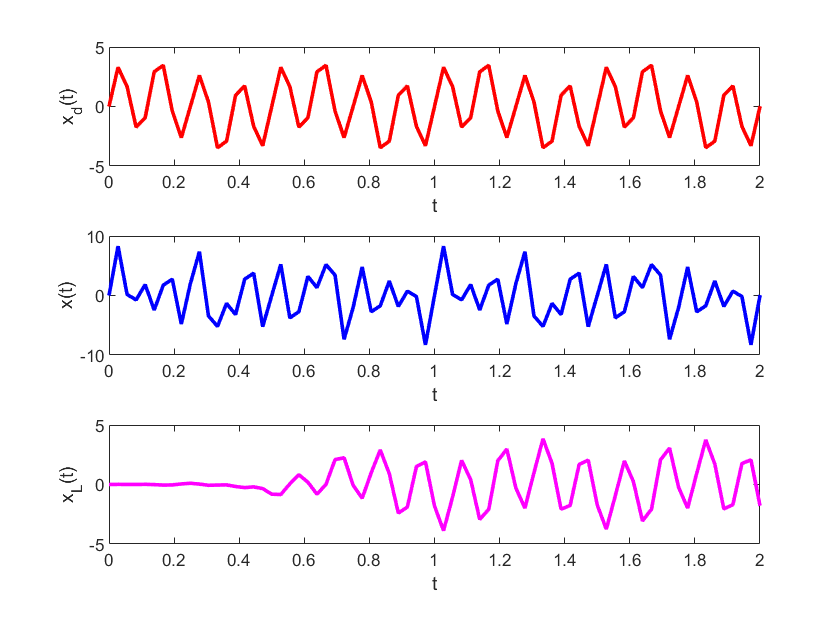

figure(2)
subplot(3,1,1);
plot(t,x13,'r-','linewidth',1.8);
xlabel('t'); ylabel('x_d(t)');
xlim([0,2]);
subplot(3,1,2);
plot(t,xn,'b-','linewidth',1.8);
xlabel('t'); ylabel('x(t)');
xlim([0,2]);

subplot(3,1,3);
plot(t,xL(1:length(t)),'m-','linewidth',1.8);
xlabel('t'); ylabel('x_L(t)');
xlim([0,2]);

function [w] = b0_Hamming(N)
        n = 0:N-1;
        w = 0.54 - 0.46*cos(2*pi*n/(N-1));
end

function [hn_BP] = a0_ThongDai(omega_c1, omega_c2, N)
    n = -(N-1)/2:(N-1)/2;
    hn_BP = zeros(1, length(n));
    for i = 1:length(n)
        if n(i) == 0
            hn_BP(i) = (omega_c2 - omega_c1) / pi;
        else
            hn_BP(i) = (sin(omega_c2*n(i)) - sin(omega_c1*n(i))) / (pi*n(i));
        end
    end
end

